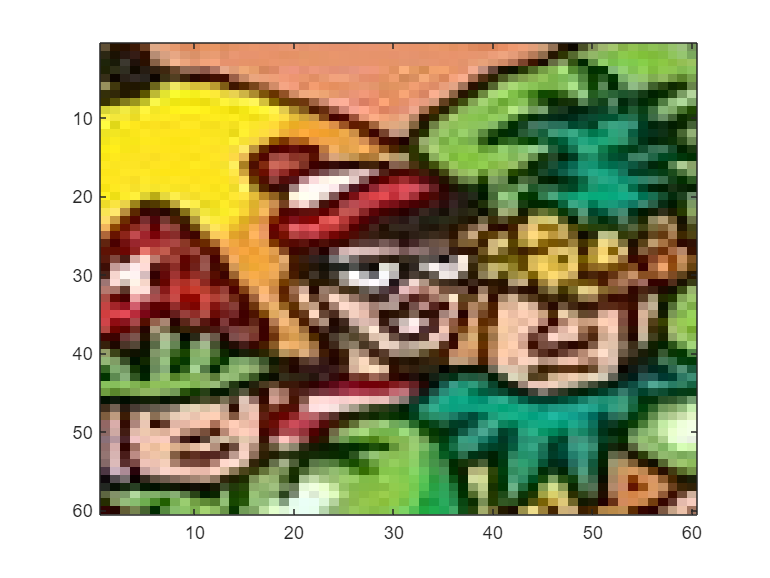

% Find Waldo via fourier spectra

% First read the clue and the complete image
clue = imread("c_clue.jpg");
% Color to grayscale
clueBW = rgb2gray(clue);
% display Image
imagesc(clue)

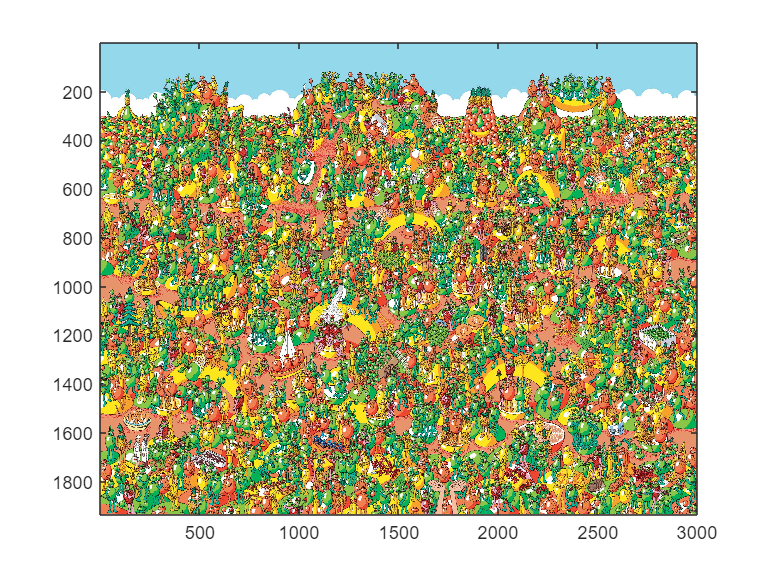

image = imread("c.jpg");
imageBW = rgb2gray(image);
imagesc(image)
colormap("gray")

% To perform the calculation we do it in one channel (grayscale)
normCrossCorrelation = normxcorr2(clueBW,imageBW);
maxNormCrossCorrelation = max(normCrossCorrelation,[],"all");
% The maximum is in the right-down edge of the 60x60 zone where the
% correlation is the most
[waldoY,waldoX] = find(normCrossCorrelation==maxNormCrossCorrelation)

waldoY = 1671

waldoX = 431

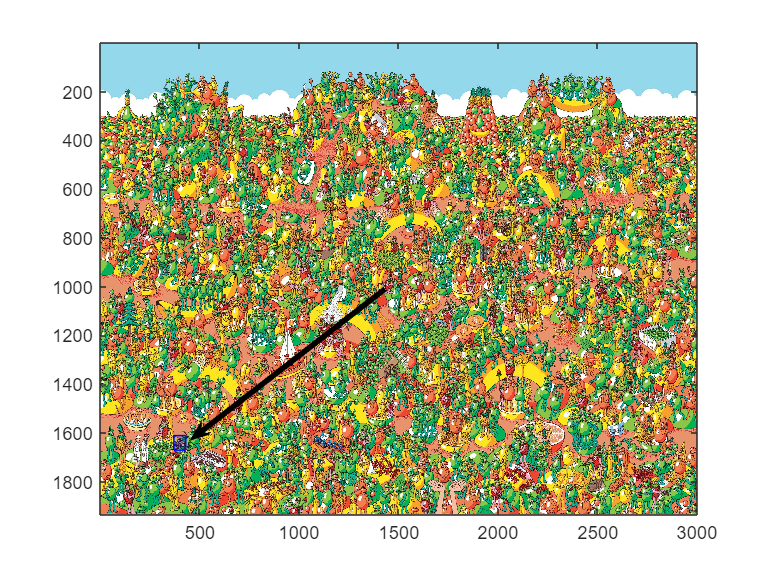

imagesc(image)
% Draw the rectangle by the center of the zone of maximum correlation in the color image 
drawrectangle('Position',[waldoX-60,waldoY-60,60,60],'Color','b','InteractionsAllowed','none','LineWidth',0.5);
annotation('arrow',[0.5 0.515-((waldoX-30)/1500)],[0.5 0.495-((1933-waldoY-15)/966)],'LineWidth',3)

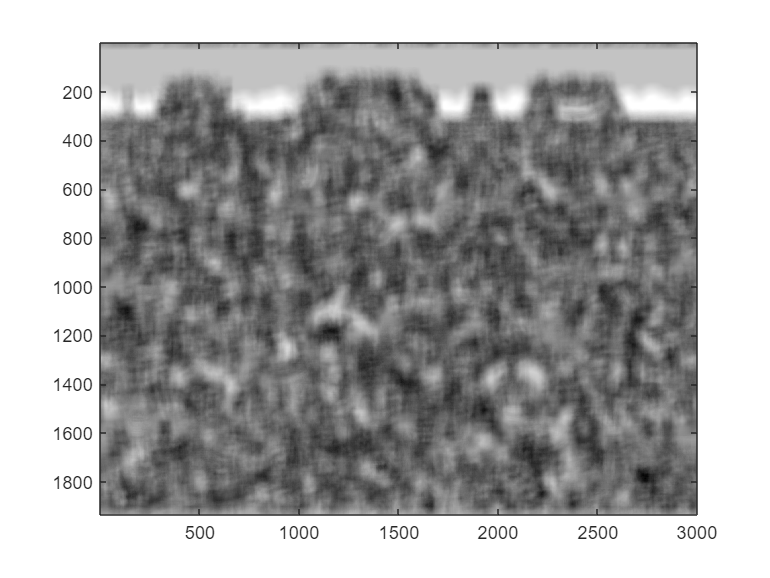

% Here we are trying to do the Cross correlation via Fourier Spectra

% Take the image and flip it in the x and y axes to perform f(-x,-y)
imageNegativeCoord = imrotate(imageBW,180); % simply rotation of 180 degrees

% Then we need to add a padding to clue image so it became the same size of
% the big image
clueSameSize = padarray(clueBW,double([round(1933/2-30), round(3000/2-30)]),0,'both');

% take off the last row because big image have odd number of rows
clueSameSize = clueSameSize(1:end-1,:);

% take the fast fourier transform of the big image flipped: F{f(-x,-y)}
FFTimageNegativeCoord = fft2(imageNegativeCoord);

% same step but with the clue sized as big image: F{g(x,y)}
FFTclue = fft2(clueSameSize);

% The Cross correlation is defined as f xcorr g = f*(-x,-y) conv g(x,y)
% and in the fourier domain it becomes 
% f xcorr g = F^-1[F{f*(-x,-y)}.F{g(x,y)}]
CrossCorrelationViaFourier = ifft2(FFTimageNegativeCoord.*FFTclue);


% Fourier cross correlation, we rotate the image again to see it 
imagesc(imrotate(log(abs(fftshift(CrossCorrelationViaFourier))),180))

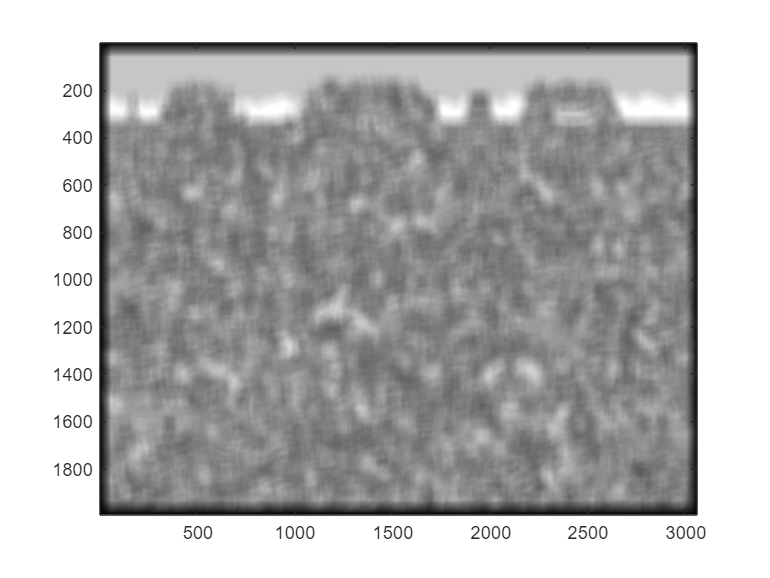

CrossCorrelationMatlab = xcorr2(imageBW,clueBW);
imagesc(CrossCorrelationMatlab)

% As we can see we can perform a cross correlation transform in the fourier
% domain
